% exp_dx = [0 2 4.75 7.4 10 12.45]/1000;
% exp_f = ([-588 0 1190 1190*2 1190*3 1190*4]+588)*9.81/1000;

exp_dx = [0 2.3 6.23 10.7 15.25]/1000;
exp_f = ([-588 0 1190 1190*2 1190*3]+588)*9.81/1000;


spring_len = (58.5)/1000;
force_pt_len = (54.5-8.6)/1000;
rotational_stiffness = []; %N.m / degree
gamma = [];
moment = [];
for i=1:length(exp_dx)
    % gamma_temp = 2*asin(exp_dx(i)/(2*spring_len));
    % moment_temp = exp_f(i)*cos(gamma_temp)*force_pt_len;
    gamma_temp = exp_dx(i)/(force_pt_len+0.004);
    moment_temp = exp_f(i)*force_pt_len;
    gamma(end+1) = gamma_temp;
    moment(end+1) = moment_temp;
end

% Fit linear model through the origin
mdl = fitlm(gamma, moment, 'Intercept', false);

% Display the model
disp(mdl);


Linear regression model:
    y ~ x1

Estimated Coefficients:
          Estimate      SE       tStat      pValue  
          ________    _______    _____    __________

    x1     6.1806     0.05112    120.9    2.8068e-08


Number of observations: 5, Error degrees of freedom: 4
Root Mean Squared Error: 0.0203


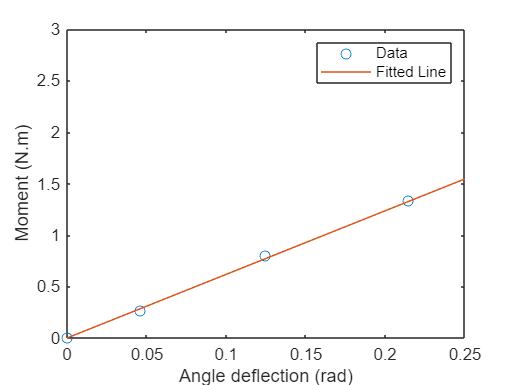


% Plot the data and the fitted line
figure;
plot(gamma, moment, 'o'); % Data points
hold on;
plot(gamma, predict(mdl, gamma'), '-'); % Fitted line
ylabel("Moment (N.m)")
xlabel("Angle deflection (rad)")
xlim([0,0.25])
ylim([0,3])
legend('Data', 'Fitted Line');
hold off;